# Opcion A

Jesus Molina Roldan

# Exercici 1

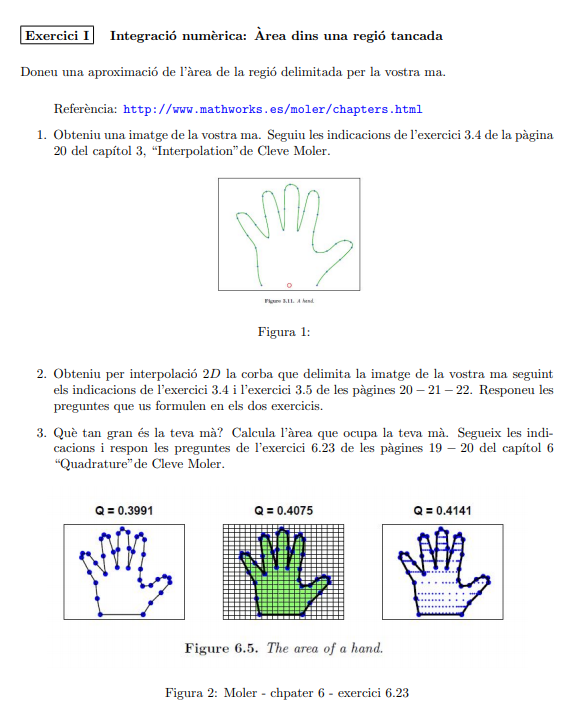

**Exercici 1.2**

clear
format long G
figure('position',get(0,'screensize'))
axes('position',[0 0 1 1])
%[x,y] = ginput;
load myhand.mat

# Splinetx

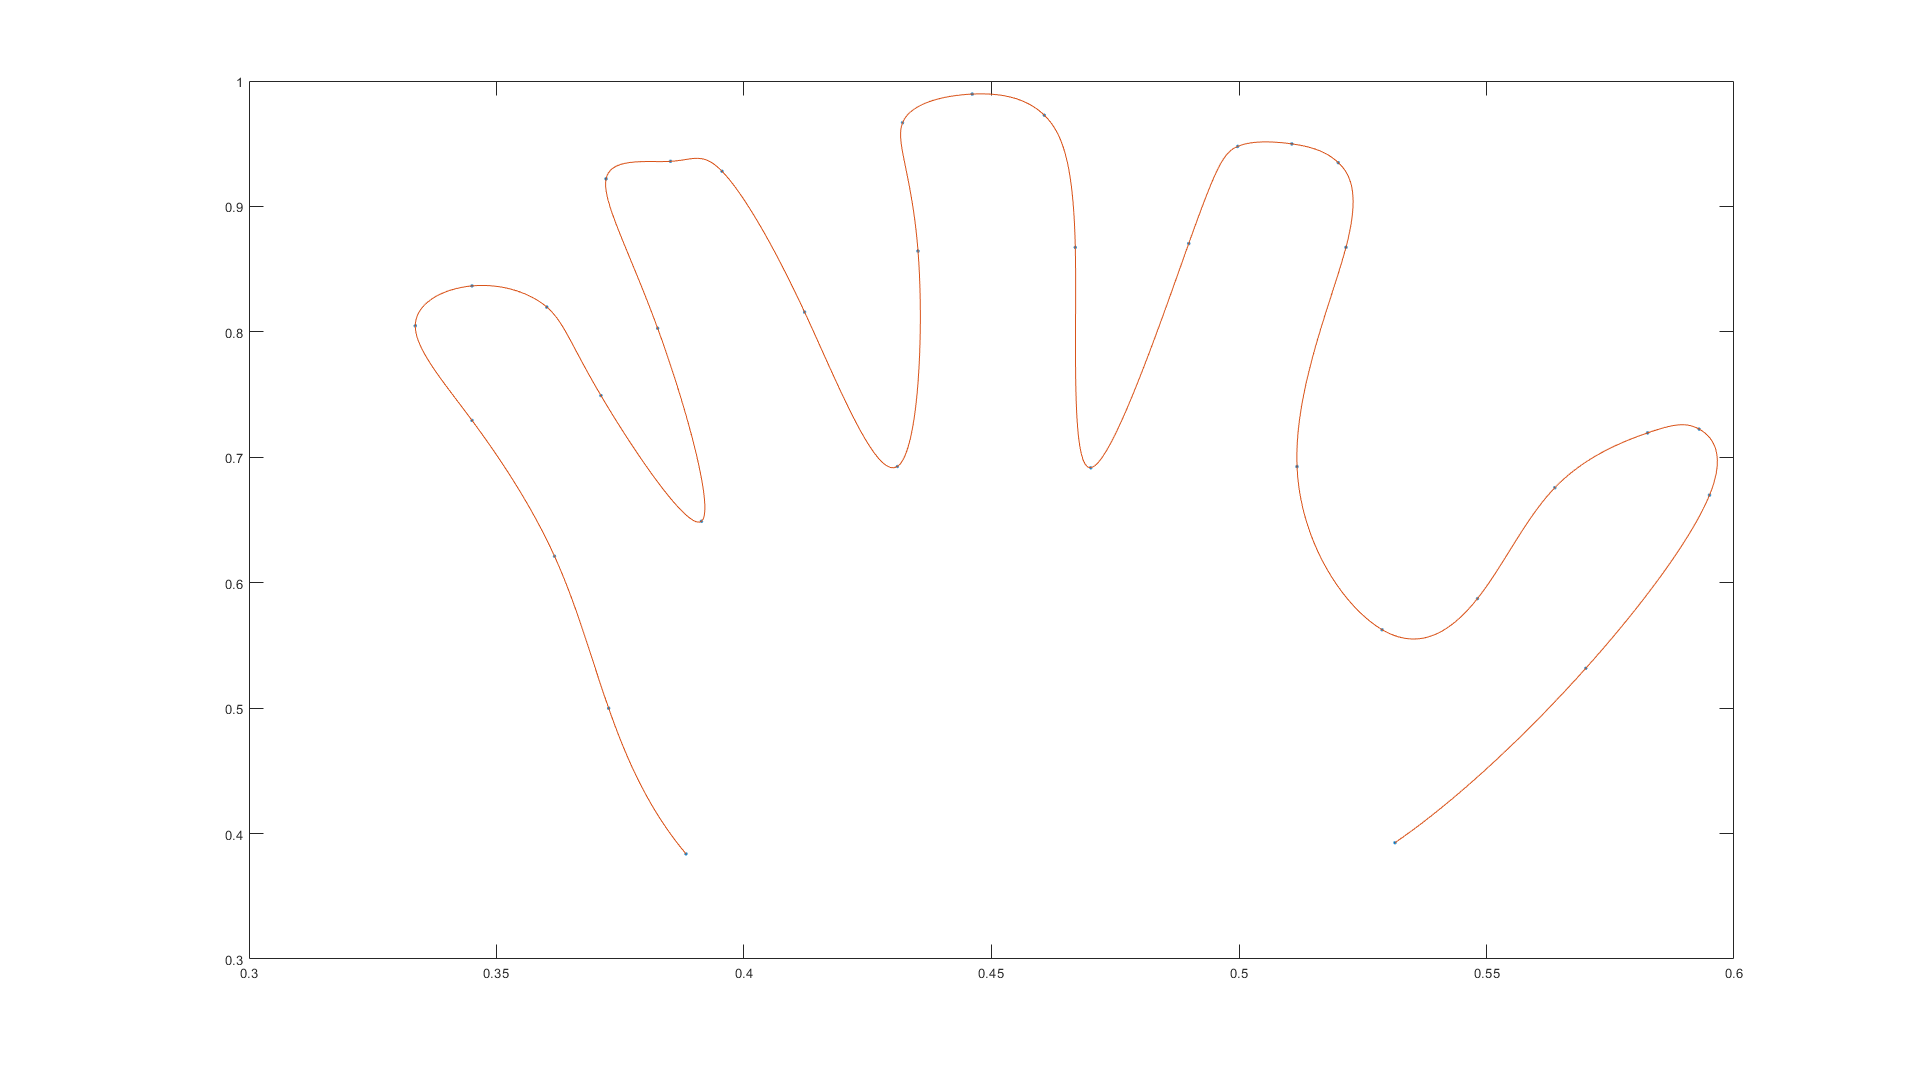

n = length(x);
s = (1:n)';
t = (1:.05:n)';
u = splinetx(s,x,t);
v = splinetx(s,y,t);
clf reset
plot(x,y,'.',u,v,'-');

# pchiptx

n = length(x);
s = (1:n)';
t = (1:.05:n)';
u = pchiptx(s,x,t);
v = pchiptx(s,y,t);
clf reset
plot(x,y,'.',u,v,'-');

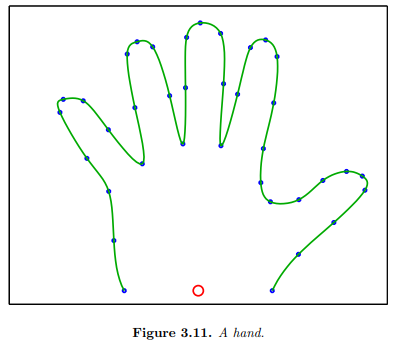

Mas o menos los plots de las manos son parecidas. Aun así prefiero la interpolacion con splinetx ya que hace mejor la forma curvada de la punta de los dedos. Creo que la figura 3.11 se ha hecho con splinetx.

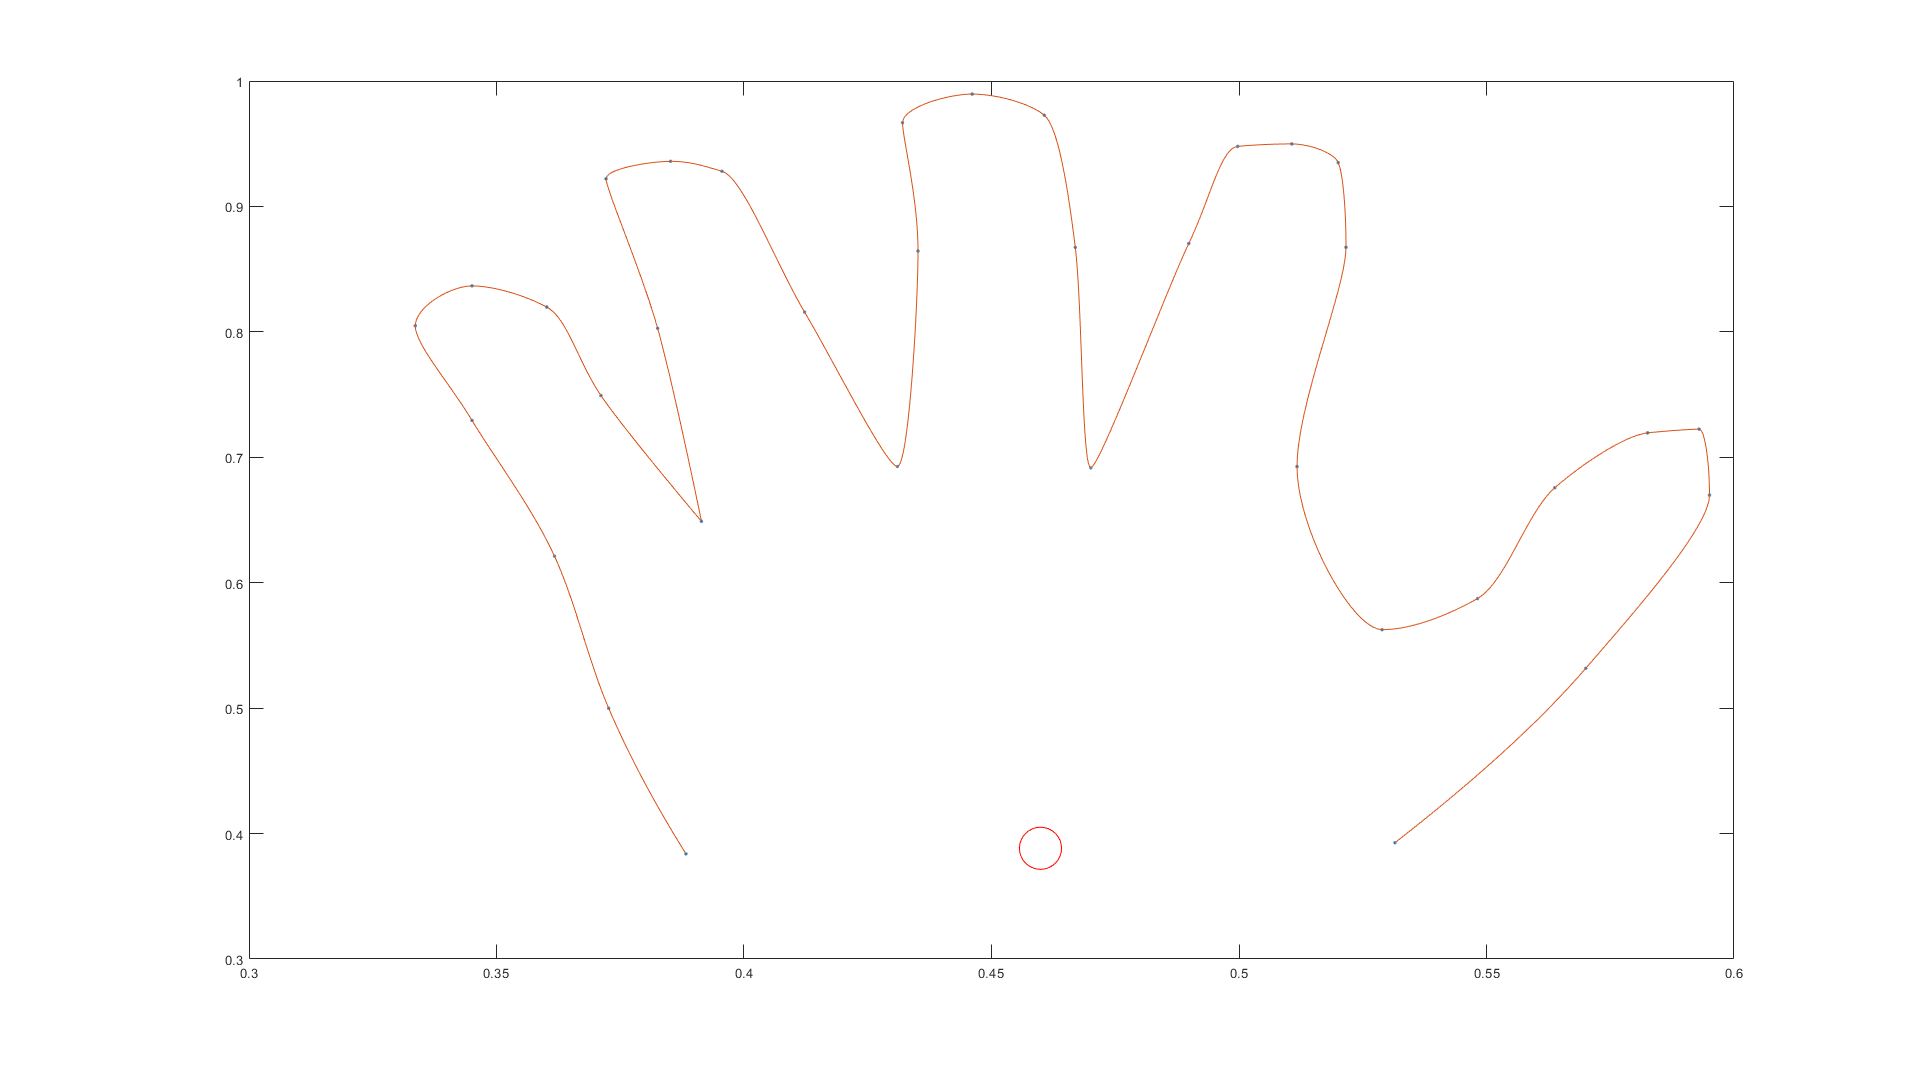

x0 = ((x(end)-x(1))/2)+x(1);
y0 = ((y(end)-y(1))/2)+y(1);
hold on
scatter(x0,y0,1000, 'red');
hold off

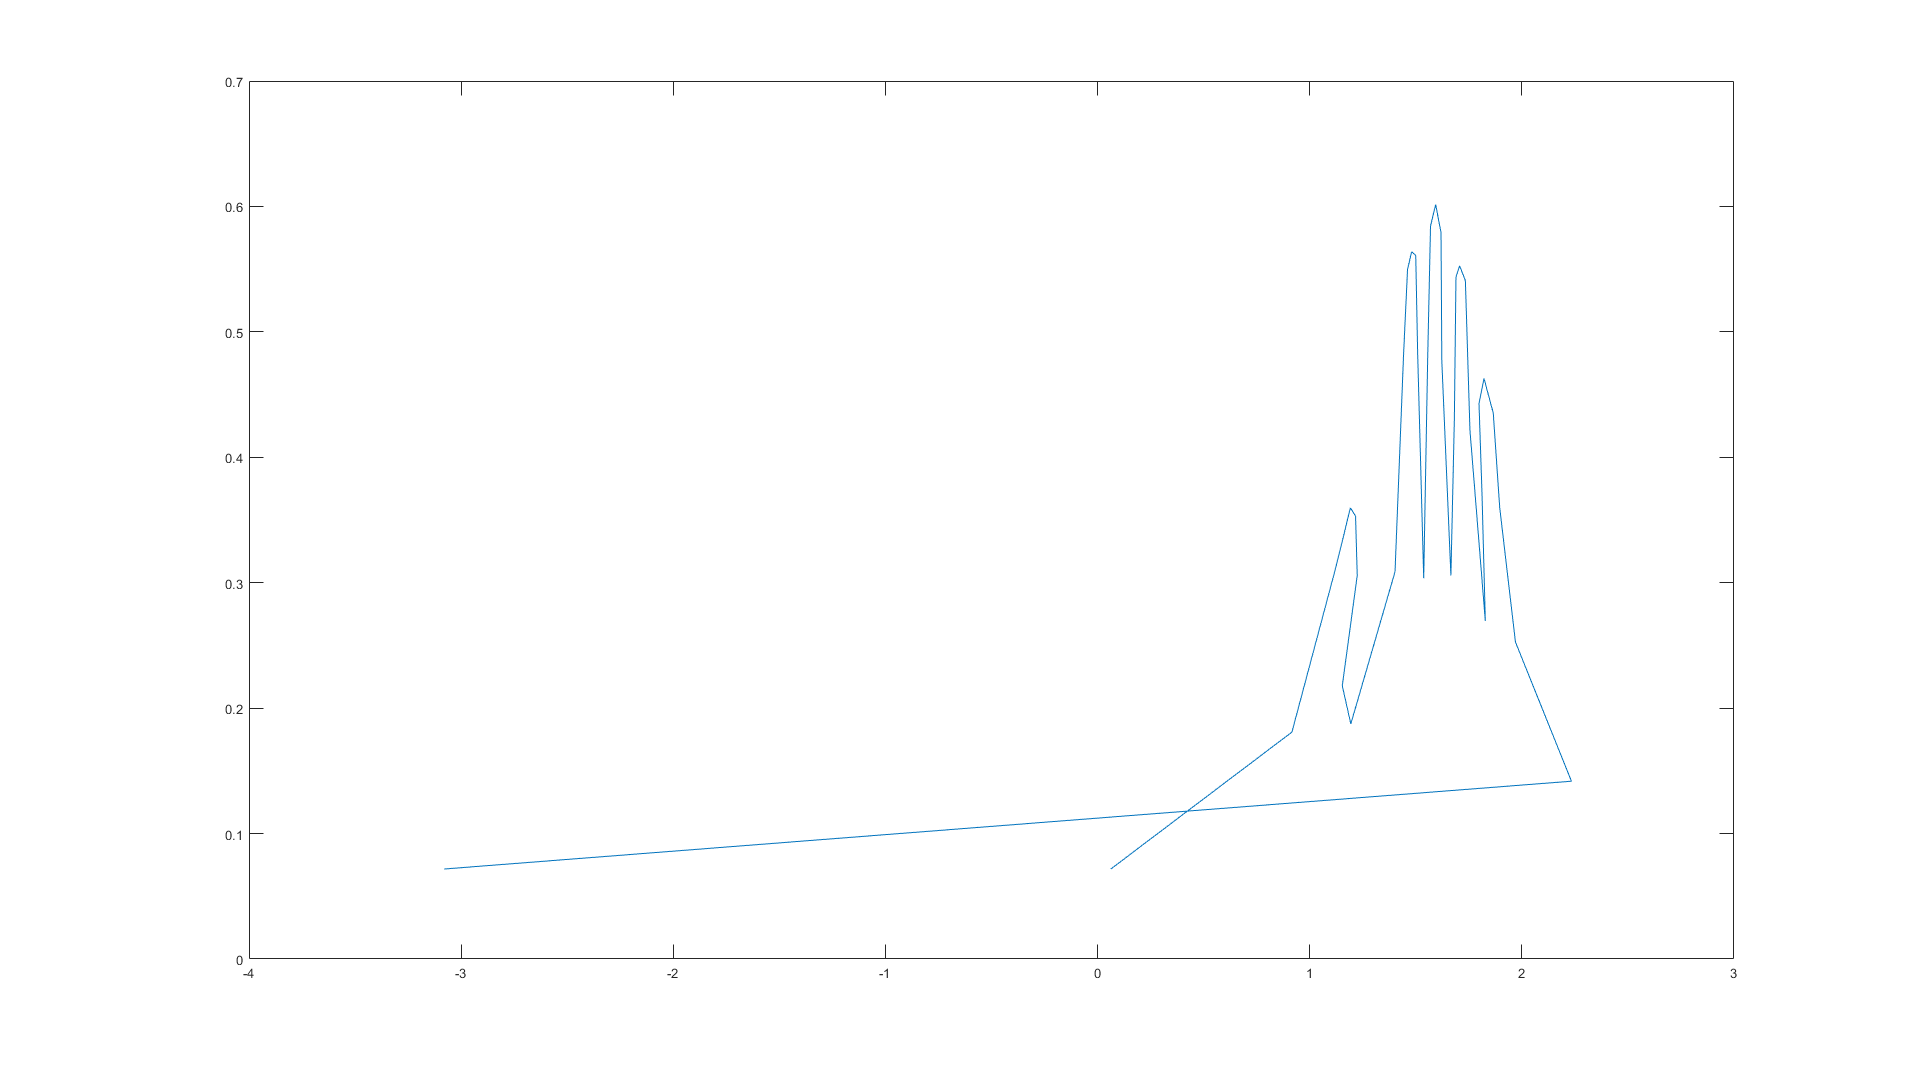

x2 = x -x0;
y2 = y - y0;
theta = atan2(y2,x2);
r = sqrt(x2.^2 + y2.^2);
plot(theta,r);

delta = .05;
t = (theta(1):delta:theta(end))';
p = pchiptx(theta,r,t);
s = splinetx(theta,r,t);

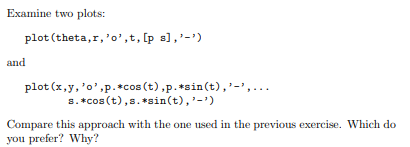

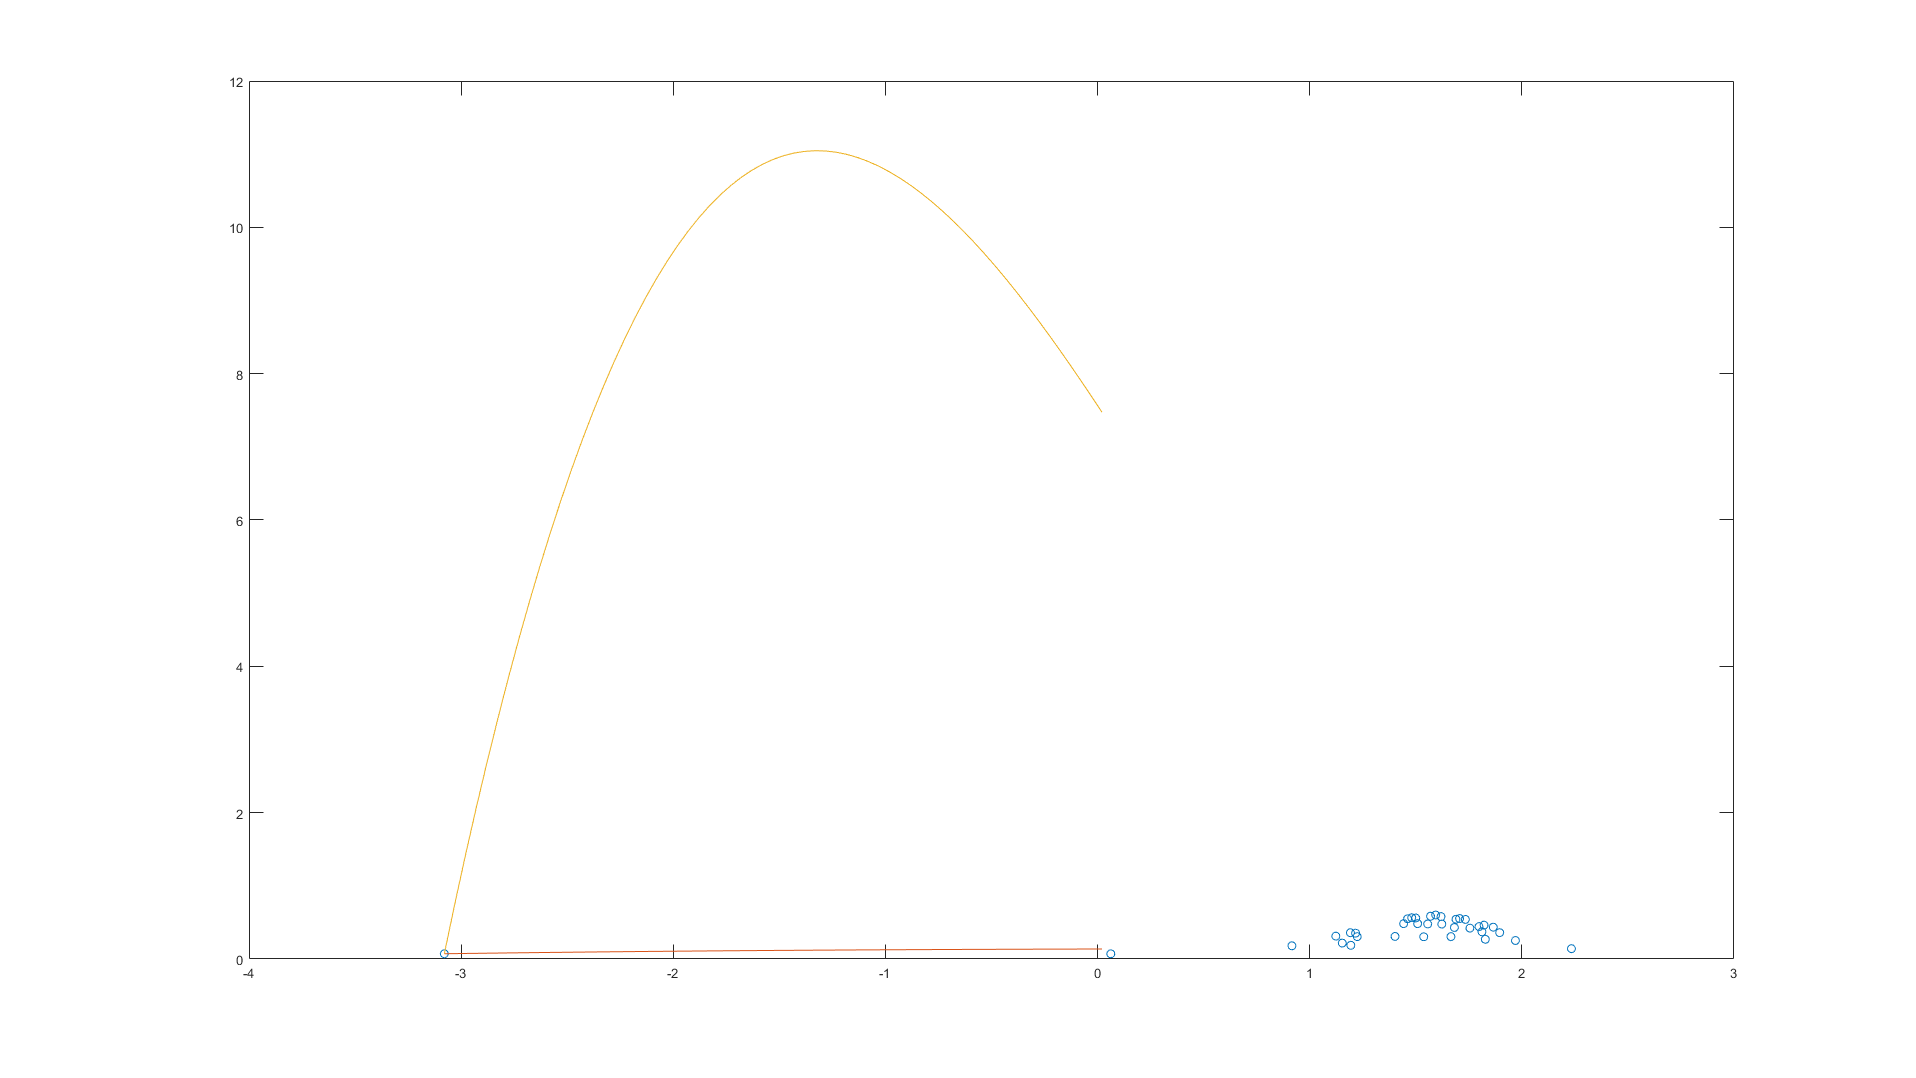

plot(theta,r,'o',t,[p s],'-')

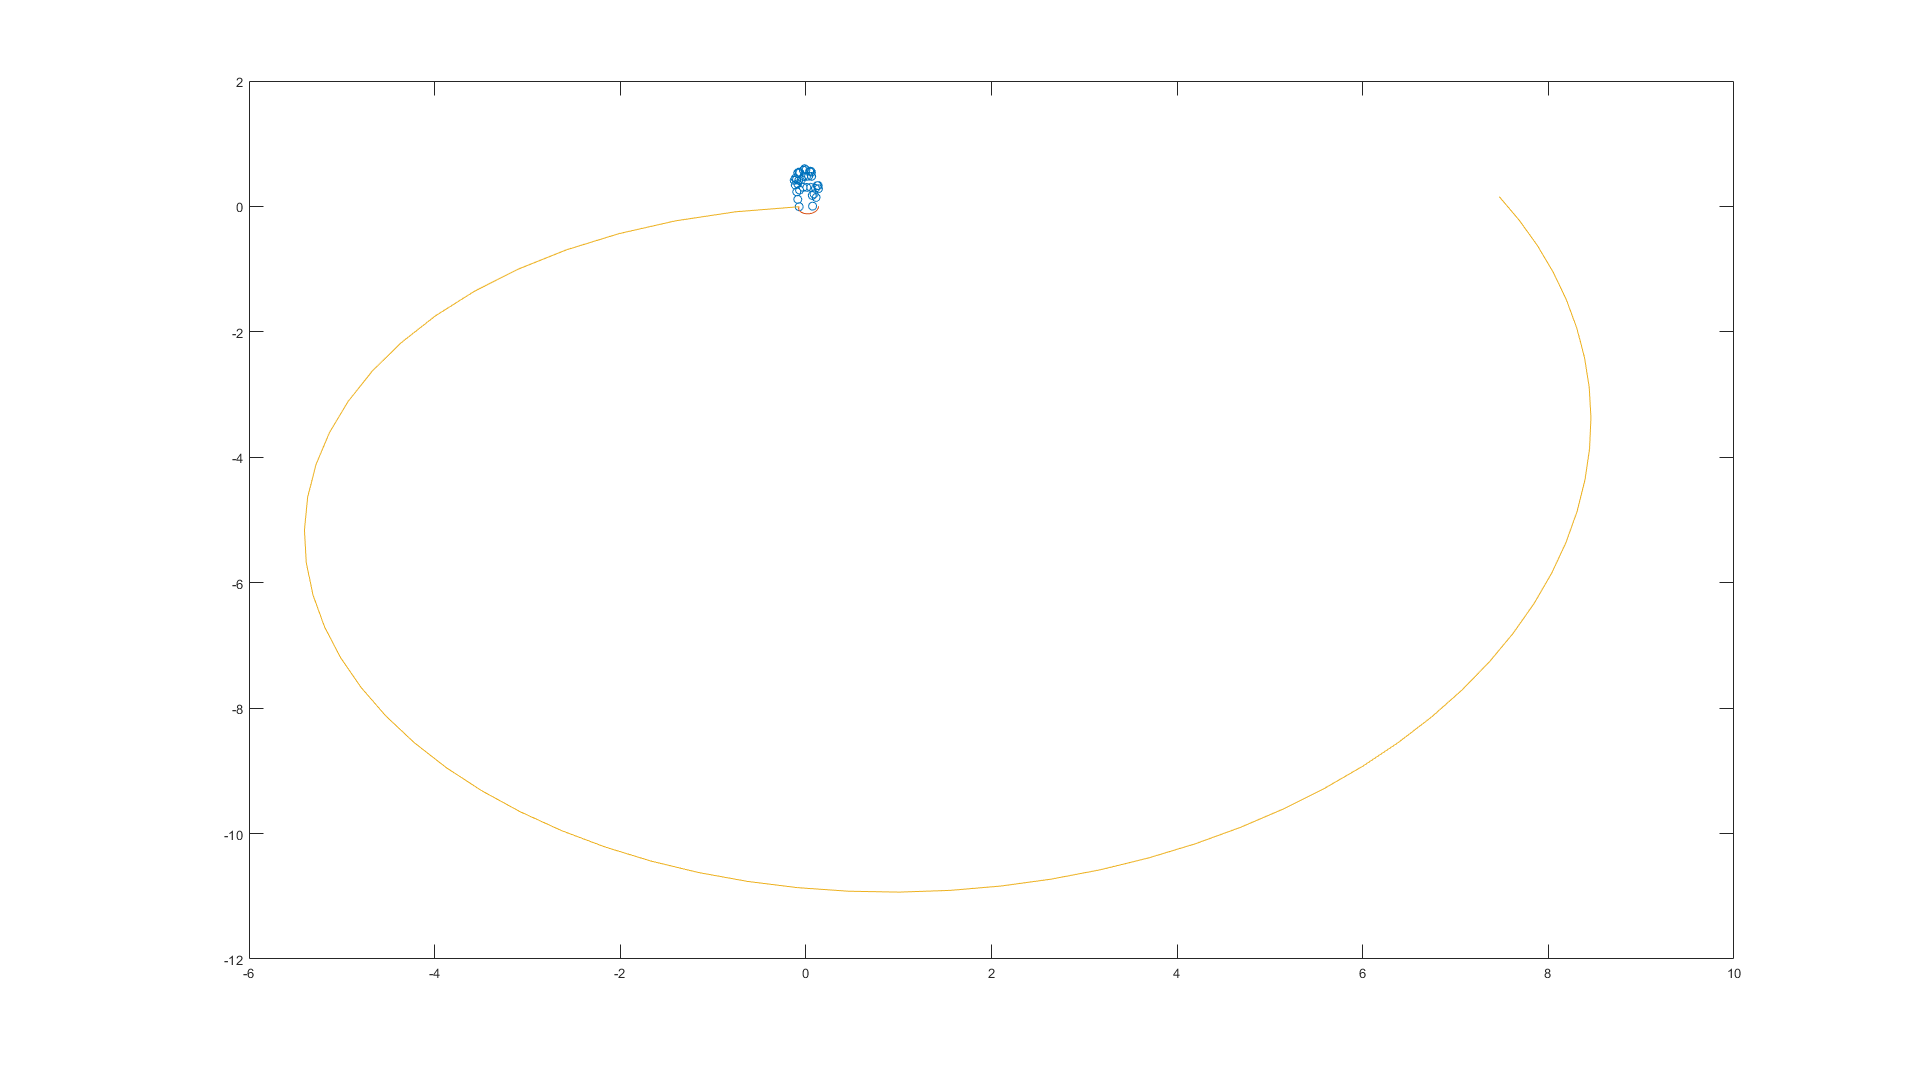

plot(x2,y2,'o',p.*cos(t),p.*sin(t),'-',...
s.*cos(t),s.*sin(t),'-')

**Exercici 1.2**

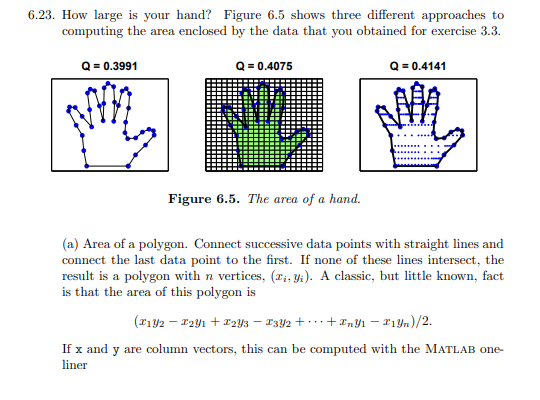

area = (x'*y([2:n 1]) - x([2:n 1])'*y)/2

area =        -0.0859964622641511


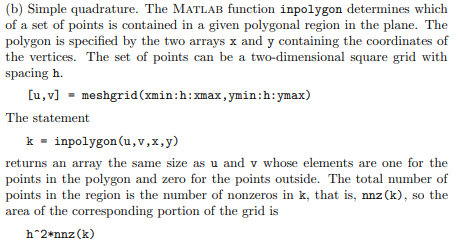

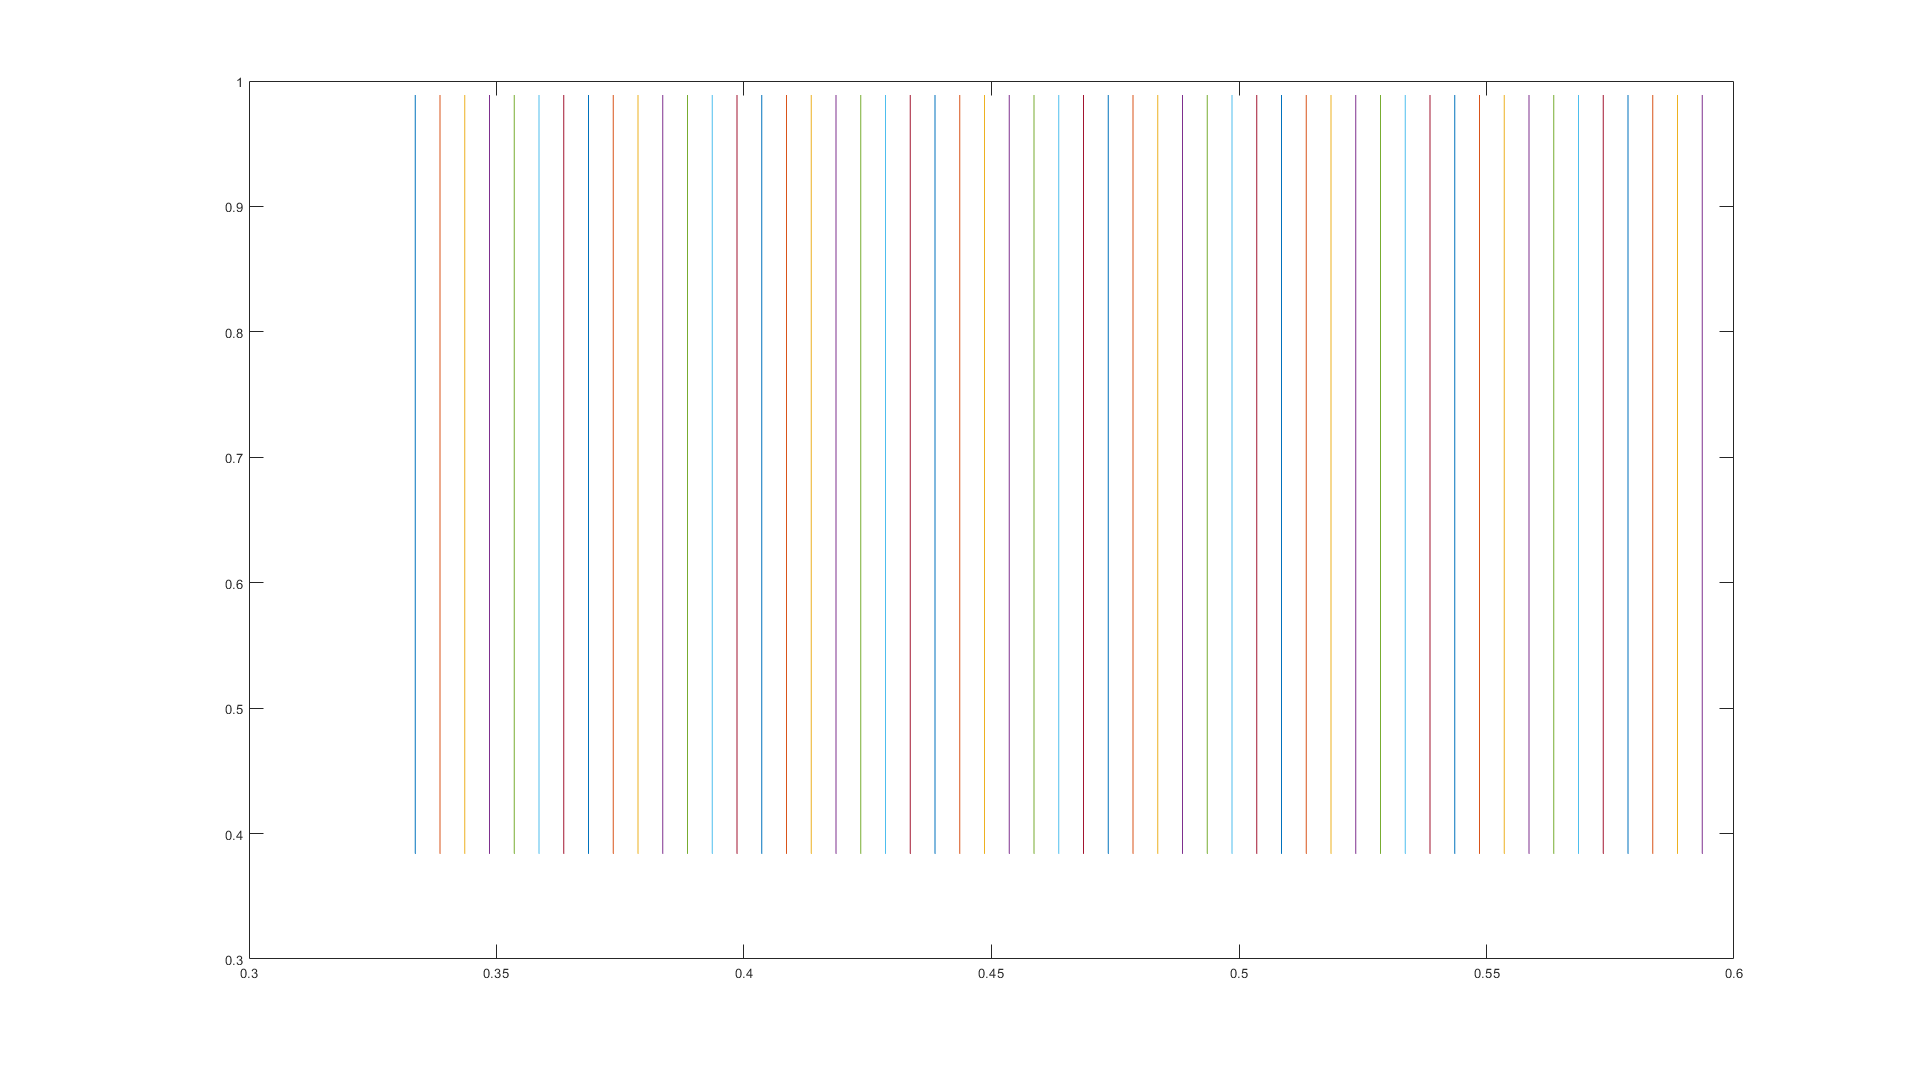

h = 0.005;
xmin = min(x);
xmax = max(x);
ymin = min(y);
ymax = max(y);
[u, v] = meshgrid(xmin:h:xmax,ymin:h:ymax);
k = inpolygon(u,v,x,y);
plot(u,v);

nnz(k);
radi = (h^2)*nnz(k)

radi =                     0.0859


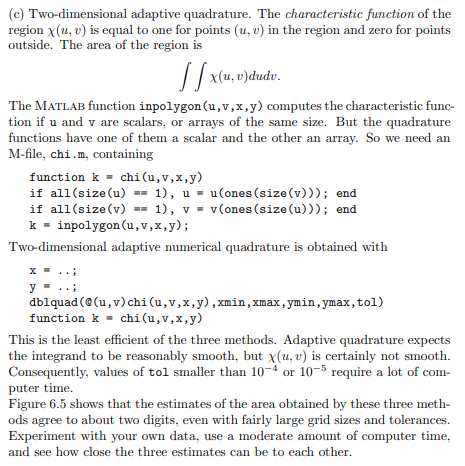

tol = 10^(-4);
radi = dblquad(@(u,v)chi(u,v,x,y),xmin,xmax,ymin,ymax,tol)

radi =         0.0863943030071044


# Exercici 2

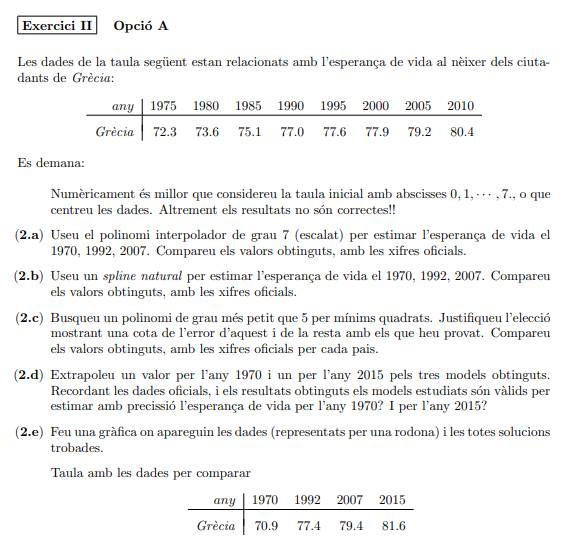

**2.a**

clear
format long G
x = [1975 1980 1985 1990 1995 2000 2005 2010];
y = [72.3 73.6 75.1 77.0 77.6 77.9 79.2 80.4];
anys = [1970 1992 2007 2015];
valor_exacto = [70.9 77.4 49.4 81.6];

# Polinomi interpolador grau 7

grau = 7;
[p, ~, mu] = polyfit(x,y,grau);
aproximado = polyval(p,anys,[], mu);
error = error_absoluto(valor_exacto,aproximado);
t = array2table(p, 'RowNames', {'coeficient polinomi'})

t = 1×8 table
                                  p1                   p2                  p3                   p4                  p5                  p6                   p7                 p8       
                           _________________    ________________    _________________    ________________    ________________    _________________    ________________    _______________

    coeficient polinomi    0.703353483285026    -1.0950000000001    -2.78935644459486    3.84687500000029    3.50060151313737    -3.82986979166686    1.32862720284717    77.452978515625


t1 = array2table([valor_exacto;aproximado; error], 'VariableNames', {'1970' ,'1992' ,'2007' ,'2015'}, 'RowNames', {'valor', 'aproximat' 'desviat'})

t1 = 3×4 table
                       1970                 1992                  2007                2015       
                 ________________    ___________________    ________________    _________________

    valor                    70.9                   77.4                49.4                 81.6
    aproximat    50.7999999999965           77.392127232    79.8143557120001     81.7000000000011
    desviat      20.1000000000035    0.00787276799995595    30.4143557120001    0.100000000001074


**2.b**

# Spline

x = (x-1975)/(35/7);
anys2 = (anys-1975)/(35/7);
aproximado = interp1(x,y,anys2,'spline');
error = error_absoluto(valor_exacto,aproximado);
t2 = array2table([valor_exacto;aproximado; error], 'VariableNames', {'1970' ,'1992' ,'2007' ,'2015'}, 'RowNames', {'valor', 'aproximat' 'desviat'})

t2 = 3×4 table
                       1970                 1992                2007                2015      
                 _________________    _________________    _______________    ________________

    valor                     70.9                 77.4               49.4                81.6
    aproximat     70.3143540669856     77.3947827751196    79.787414354067    79.7961722488039
    desviat      0.585645933014376    0.005217224880397    30.387414354067    1.80382775119611


**2.c**

# Polinomio minimos cuadrados

n = 5;
error = zeros(n,length(anys2)+1);
RowNames = {};
for i = 1:n
    coeficientes = polinomio_interpolador_minimos_cuadrados(x, y, i);
    aproximado = polyval(coeficientes,anys2);
    RowNames{i} = strcat('grau ', int2str(i));
    e = error_absoluto(valor_exacto, aproximado);
    error(i,:) = [e, sum(e,2)];
end
t3 = array2table(error,'VariableNames', {'1970' ,'1992' ,'2007' ,'2015', 'Desviacio'}, 'RowNames',RowNames)

t3 = 5×5 table
                   1970                 1992                 2007                 2015              Desviacio    
             _________________    _________________    ________________    __________________    ________________

    grau1    0.717857142857156    0.874047619047616     30.472380952381    0.0571428571428498    32.1214285714286
    grau2    0.201785714285364    0.552785714285818    30.2786428571429     0.862499999999713    31.8957142857138
    grau3      1.1142857142829    0.535752380952502     30.233736796537    0.0499999999976239      31.93377489177
    grau4     1.28035714287641    0.275640952379177    29.9764118614701       2.4446428571583     33.977052813884
    grau5     4.32499999959218    0.252492923

Como podemos ver el polinomio de minimos cuadrados que da mejor resultado es el de grado 2, ya que es el que tiene menor error absoluto.

**2.d**

Como podemos ver en los resultados del polinomio de grado 7 se desvia mucho del valor correcto respecto al año 1970. Por lo que consideraria que no es muy valido. En contraposición el polinomio realizado con spline es mejor ya que la desviación del año 1970 es de 0.6 y la del 2015 de 1.8. El polinomio de grado 3 realizado con minimos cuadrados es el que da mejor resultado ya que el error absoluto del año 1970 es de 1.11 y el del año 2015 ,0.049, dando como cifras correctas 1. 

**2.e**

# Dades

x = [1975 1980 1985 1990 1995 2000 2005 2010];
y = [72.3 73.6 75.1 77.0 77.6 77.9 79.2 80.4];
scatter(x,y, 'DisplayName','Dades 1');
anys = [1970 1992 2007 2015];
valor_exacto = [70.9 77.4 49.4 81.6];
hold on;
scatter(anys, valor_exacto, 'DisplayName','Dades 2');

# Polinomi interpolador grau 7(PLOT)

grau = 7;
[coeficientes, ~, mu] = polyfit(x,y,grau);
xplot = 1970:2015;
yplot = polyval(coeficientes,xplot,[], mu);
hold on;
plot(xplot,yplot, 'DisplayName','polinomi grau 7');

# Spline(PLOT)

x = (x-1975)/(35/7);
xplot_centrado = ((1970:2015)-1975)/(35/7);
yplot = interp1(x,y,xplot_centrado,'spline');
xplot = 1970:2015;
hold on;
plot(xplot,yplot, 'DisplayName','spline');

# Polinomio minimos cuadrados(Plot)

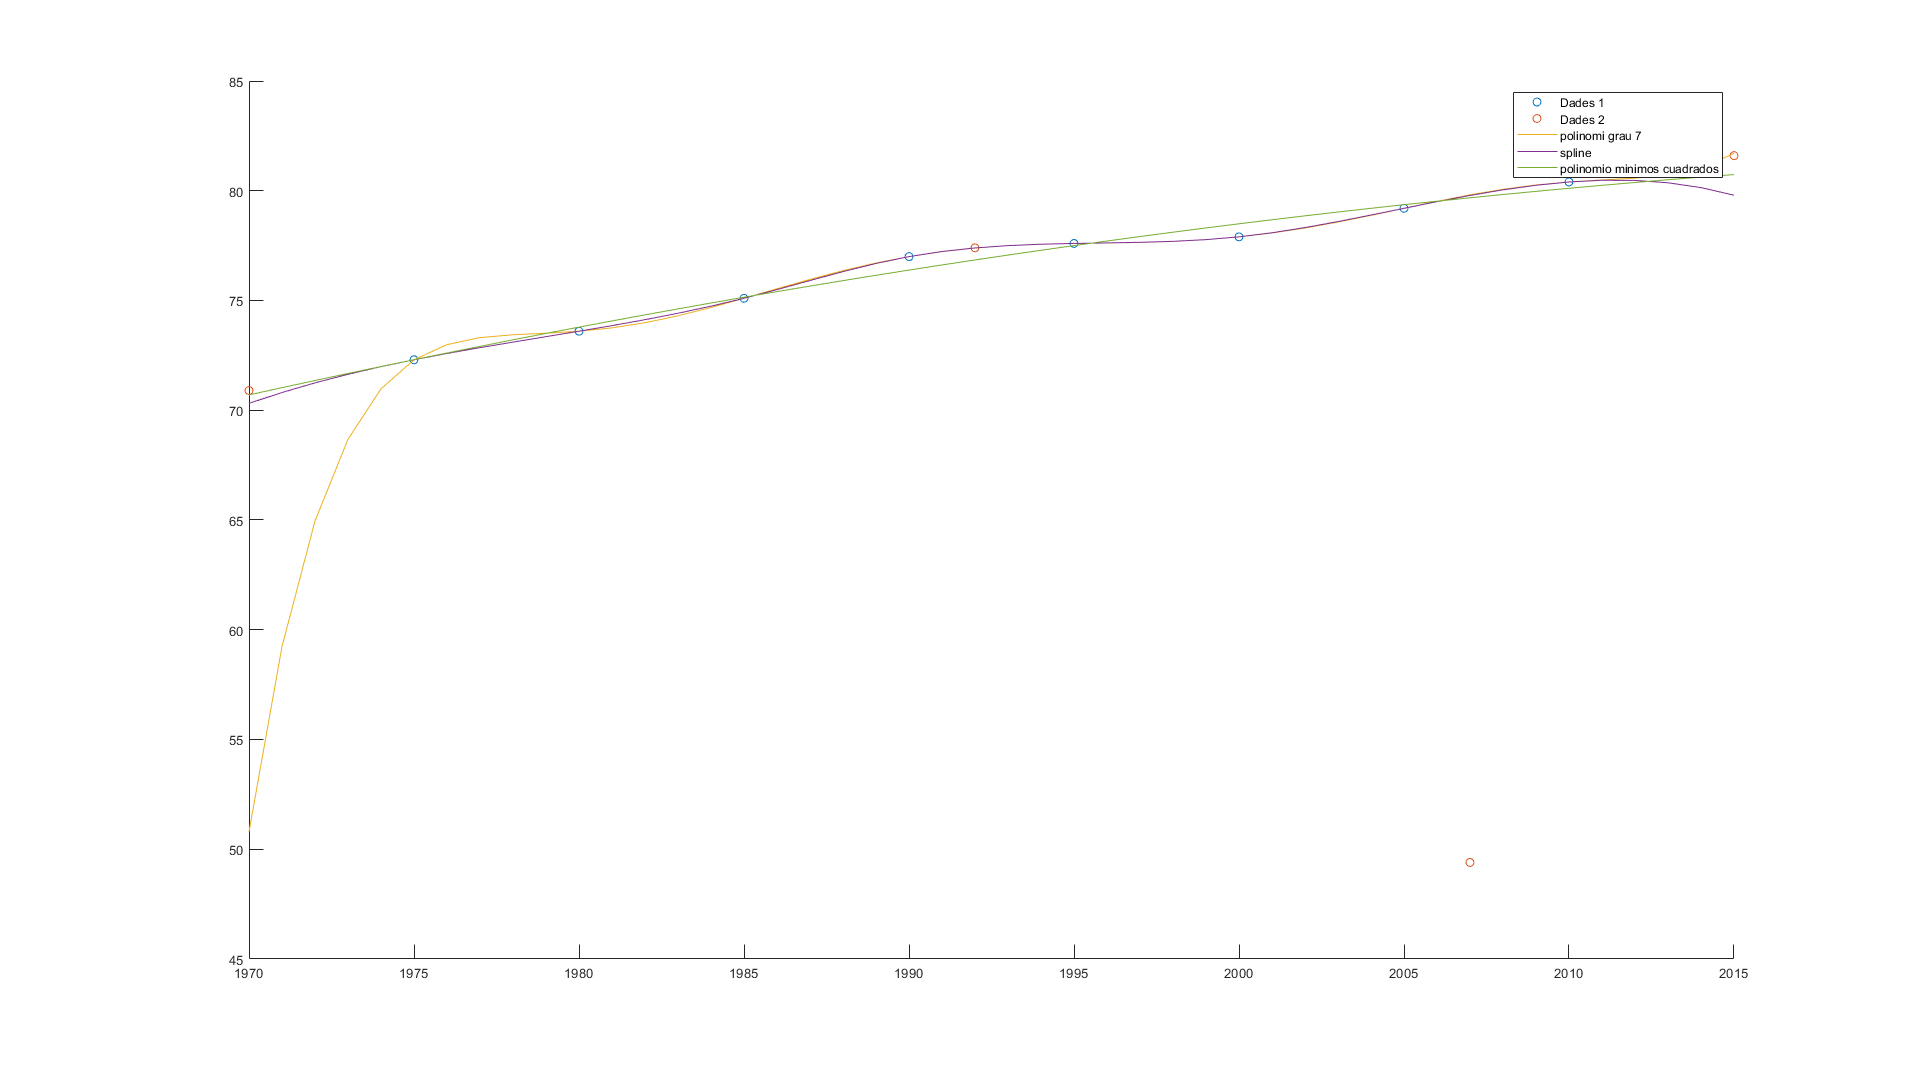

grado = 2;
[coeficientes] = polinomio_interpolador_minimos_cuadrados(x, y, grado);
xplot_centrado = ((1970:2015)-1975)/(35/7);
yplot = polyval(coeficientes,xplot_centrado);
xplot = 1970:2015;
hold on;
plot(xplot,yplot, 'DisplayName','polinomio minimos cuadrados');
legend
hold off;

# Exercici 3

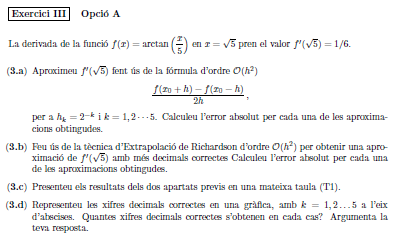

**3.a**

# Central difference approximation

clear
format long G
syms f(x) x
f(x) = atan(x/5);
point = sqrt(5);
iterations = 5;
df = diff(f,x);
dfx = double(df(point));
N = 1;
[T, resultat] = extrapolation_richardson(f,point,iterations, N);
t = array2table(T,'VariableNames',{'baske^k', 'N1','error'})

t = 5×3 table
    baske^k           N1                   error        
    _______    _________________    ____________________

        0.5    0.166511074391863    0.000155592274803551
       0.25    0.166628006275172    3.86603914946382e-05
      0.125    0.166657016585081    9.65008158612668e-06
     0.0625    0.166664255087324    2.41157934249836e-06
    0.03125    0.166666063830687    6.02835980051397e-07


# Extrapolation richardson

**3.b**

N = 5;
[T, resultat] = extrapolation_richardson(f,point,iterations, N);
t = array2table(T,'VariableNames', {'base^k', 'N1', 'N2', 'N3', 'N4', 'N5', 'error'})

t = 5×7 table
    base^k            N1                   N2                   N3                   N4                   N5                   error        
    _______    _________________    _________________    _________________    _________________    _________________    ____________________

        0.5    0.166511074391863                    0                    0                    0                    0                       0
       0.25    0.166628006275172    0.166666983569608                    0                    0                    0                       0
      0.125    0.166657016585081    0.166666686688383    0.166666666896302                    0                    0                       0
     0.0625    0.166664255087324    0.1666

**3.c**

N1 consiste en la central difference approximation por lo tanto ya he mostrado una tabla con los dos apartados anteriores en el ejercicio 3b.

**3.d**

iterations = 5;
point = sqrt(5);
N_total = 5;
w = 1;
for N = 1:N_total
    [T, resultat] = extrapolation_richardson(f,point,iterations, N);
    VariableNames = {'base^k'};
    for i = 1:N
        VariableNames{i+1} = strcat('N ', int2str(i));
    end
    VariableNames{end+1} = 'error';
    t = array2table(T,'VariableNames',VariableNames)
    xplot = w:N_total;
    yplot = xifres_decimals_correctes(1/6, resultat(w:end,w));
    plot(xplot,yplot, 'DisplayName', strcat('N',int2str(N),'(h)'));
    if(N == 1)
        hold on;
    end
    w = w + 1;
end

t = 5×3 table
    base^k            N1                   error        
    _______    _________________    ____________________

        0.5    0.166511074391863    0.000155592274803551
       0.25    0.166628006275172    3.86603914946382e-05
      0.125    0.166657016585081    9.65008158612668e-06
     0.0625    0.166664255087324    2.41157934249836e-06
    0.03125    0.166666063830687    6.02835980051397e-07


t = 5×4 table
    base^k            N1                   N2                   error        
    _______    _________________    _________________    ____________________

        0.5    0.166511074391863                    0                       0
       0.25    0.166628006275172    0.166666983569608    3.16902941666086e-07
      0.125    0.166657016585081    0.166666686688383    2.00217167012351e-08
     0.0625    0.166664255087324    0.166666667921405    1.25473870182802e-09
    0.03125    0.166666063830687    0.166666666745141    7.84740883386092e-11


t = 5×5 table
    base^k            N1                   N2                   N3                   error        
    _______    _________________    _________________    _________________    ____________________

        0.5    0.166511074391863                    0                    0                       0
       0.25    0.166628006275172    0.166666983569608                    0                       0
      0.125    0.166657016585081    0.166666686688383    0.166666666896302     2.2963503321094e-10
     0.0625    0.166664255087324    0.166666667921405    0.166666666670273    3.60683705125098e-12
    0.03125    0.166666063830687    0.166666666745141    0.166666666666723    5.64270852265736e-14


t = 5×6 table
    base^k            N1                   N2                   N3                   N4                   error        
    _______    _________________    _________________    _________________    _________________    ____________________

        0.5    0.166511074391863                    0                    0                    0                       0
       0.25    0.166628006275172    0.166666983569608                    0                    0                       0
      0.125    0.166657016585081    0.166666686688383    0.166666666896302                    0                       0
     0.0625    0.166664255087324    0.166666667921405    0.166666666670273    0.166666666666686    1.90958360235527e-14
    0.03125    0.166666063830687    0.166666666745141    0.16

t = 5×7 table
    base^k            N1                   N2                   N3                   N4                   N5                   error        
    _______    _________________    _________________    _________________    _________________    _________________    ____________________

        0.5    0.166511074391863                    0                    0                    0                    0                       0
       0.25    0.166628006275172    0.166666983569608                    0                    0                    0                       0
      0.125    0.166657016585081    0.166666686688383    0.166666666896302                    0                    0                       0
     0.0625    0.166664255087324    0.1666

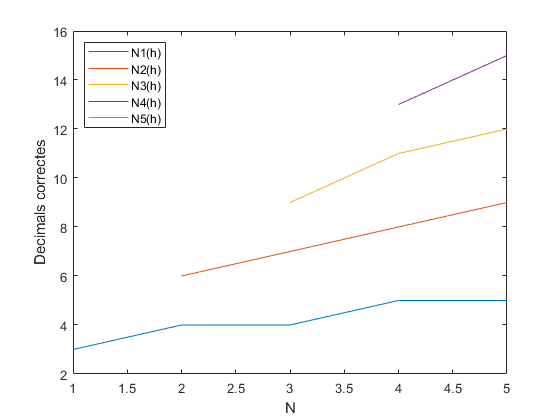

legend('Location', 'northwest');
ylabel('Decimals correctes'), xlabel('N')    
hold off

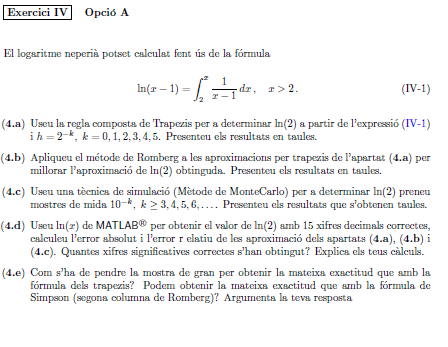

**4.a**

# **Regla composta de Trapezis**

clear
format long G
f = @(x) 1./(x-1);
base = 1/2;
iterations = 6;
a = 2;
b = 3;
[T, ~] = regla_composta_trapezis_iterations(f, a, b, base, iterations);
t = array2table(T,'VariableNames', {'k' ,'h' ,'valor' ,'error'})

t = 6×4 table
    k       h             valor                 error        
    _    _______    _________________    ____________________

    0          1                 0.75      0.0568528194400545
    1        0.5    0.708333333333333      0.0151861527733878
    2       0.25    0.697023809523809     0.00387662896386398
    3      0.125     0.69412185037185     0.00097466981190486
    4     0.0625    0.693391202207527    0.000244021647581194
    5    0.03125    0.693208208269249    6.10277093032741e-05


**4.b**

# **Metode Romberg**

N = 4;
[T , ~] = metode_romberg(f,a,b,iterations, N);
VariableNames = {'k', 'h'};
for i = 1:N
    VariableNames{end+1} = strcat('R_', int2str(i));
end
VariableNames{end+1} = 'errAbs';
t = array2table(T, 'VariableNames', VariableNames)

t = 6×7 table
    k       h               R_1                  R_2                  R_3                  R_4                  errAbs       
    _    ________    _________________    _________________    _________________    _________________    ____________________

    0         0.5                 0.75                    0                    0                    0                       0
    1        0.25    0.708333333333333    0.694444444444444                    0                    0                       0
    2       0.125    0.697023809523809    0.693253968253968    0.693174603174603                    0                       0
    3      0.0625     0.69412185037185    0.693154530654531    0.693147901481235    0.693147477644832    2.9708488669

**4.c**

# **Metode Montecarlo**

M =         1000


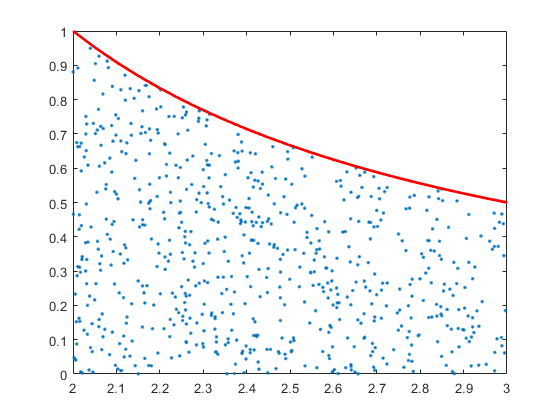

M =        10000


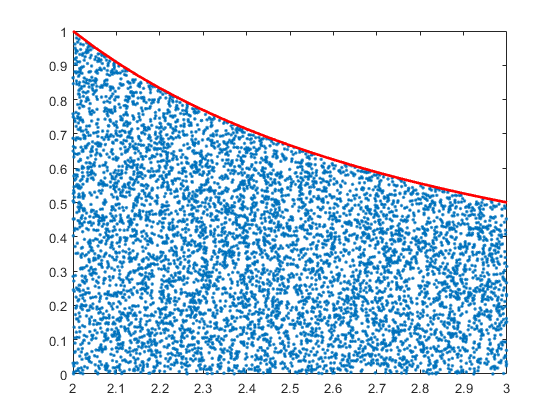

M =       100000


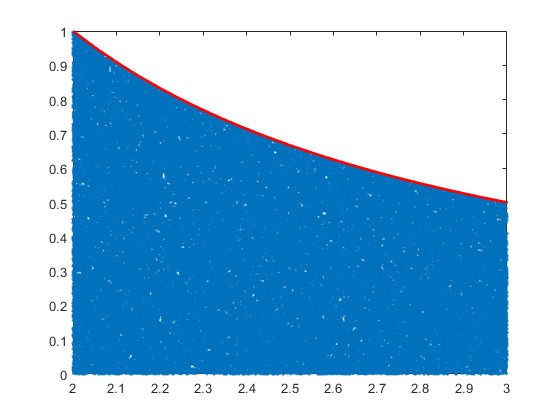

M =      1000000


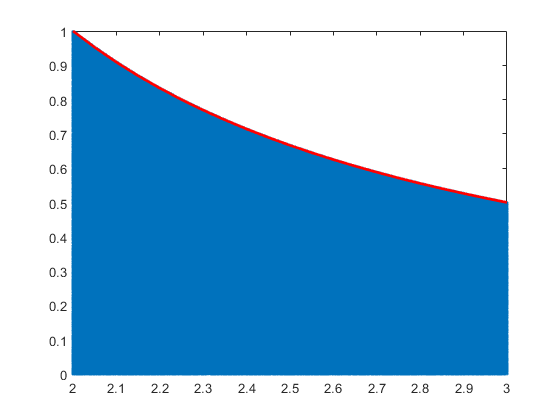

M =     10000000


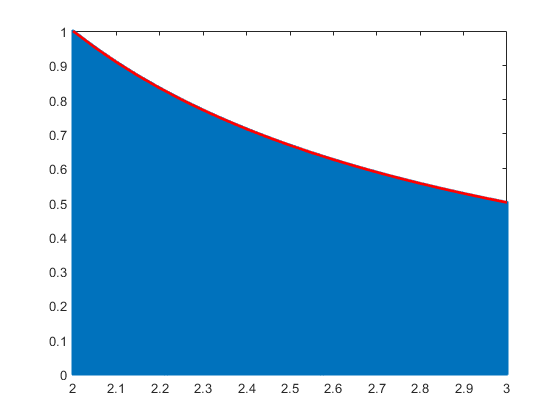

T = zeros(5,1);
for k = 3:7
    M = 10^k
    [resultat, points] = metode_montecarlo(f,a,b, M);
    T(k-2) = resultat;
    t = a:0.05:b; yt = f(t);
    figure
    plot(points(:,1),points(:,2),'.',t,yt,'r','LineWidth',2)
end

k = (3:7)';
M = (ones(5,1)*10).^k;
T = [k M T error_absoluto(T,log(2))];
t = array2table(T, 'VariableNames', {'k', 'M', 'va_ln2', 'errAbs'})

t = 5×4 table
    k       M         va_ln2             errAbs       
    _    ________    _________    ____________________

    3        1000        0.696     0.00285281944005467
    4       10000       0.6891     0.00404718055994524
    5      100000      0.69309    5.71805599453024e-05
    6     1000000      0.69347    0.000322819440054745
    7    10000000    0.6933562    0.000209019440054692


**4.d**

# **Errors**

# **Error Trapezis**

k = (0:5)';
[~, resultat] = regla_composta_trapezis_iterations(f, a, b, base, iterations);
error_absoluto_trapezis = error_absoluto(log(2),resultat);
error_relativo_trapezis = error_relativo(log(2),resultat);
xifres = xifres_significatives_correctes(log(2),resultat);
T = [k error_absoluto_trapezis error_relativo_trapezis xifres];
t = array2table(T, 'VariableNames',{'k', 'errAbs', 'errRel', 'xifres'})

t = 6×4 table
    k           errAbs                  errRel           xifres
    _    ____________________    ____________________    ______

    0      0.0568528194400547      0.0820212806667226      0   
    1       0.015186152773388       0.021908987296349      1   
    2      0.0038766289638642     0.00559279338153341      1   
    3    0.000974669811905082     0.00140615130413964      2   
    4    0.000244021647581416    0.000352048820835263      3   
    5    6.10277093034961e-05    8.80443735689671e-05      3   


# **Error absolut Romberg**

N = 4;
h = (1/2).^k;
[~ ,taula_romberg] = metode_romberg(f,a,b, iterations, N);
error_absoluto_romberg = error_absoluto(log(2),taula_romberg);
for i = 1:iterations
    for j = (i+1):N
        error_absoluto_romberg(i,j) = 0;
    end
end
VariableNames = {'k', 'h'};
for i = 1:N
    VariableNames{end+1} = strcat('ER_', int2str(i));
end
T = [k h error_absoluto_romberg];
t = array2table(T, 'VariableNames',VariableNames)

t = 6×6 table
    k       h               ER_1                    ER_2                    ER_3                    ER_4        
    _    _______    ____________________    ____________________    ____________________    ____________________

    0          1      0.0568528194400547                       0                       0                       0
    1        0.5       0.015186152773388     0.00129726388449902                       0                       0
    2       0.25      0.0038766289638642    0.000106787694023058    2.74226146579348e-05                       0
    3      0.125    0.000974669811905082    7.35009458541214e-06    7.20921289554255e-07    2.97084886913268e-07
    4     0.0625    0.000244021647581416    4.72259473527359e-07    1.37371327646463e-08    2.511987506

# **Error relatiu Romberg**

error_relativo_romberg = error_relativo(log(2),taula_romberg);
for i = 1:iterations
    for j = (i+1):N
        error_relativo_romberg(i,j) = 0;
    end
end
VariableNames = {'k', 'h'};
for i = 1:N
    VariableNames{end+1} = strcat('ER_', int2str(i));
end
T = [k h error_relativo_romberg];
t = array2table(T, 'VariableNames',VariableNames)

t = 6×6 table
    k       h               ER_1                    ER_2                    ER_3                    ER_4        
    _    _______    ____________________    ____________________    ____________________    ____________________

    0          1      0.0820212806667226                       0                       0                       0
    1        0.5       0.021908987296349     0.00187155617289109                       0                       0
    2       0.25     0.00559279338153341    0.000154062076595034    3.95624701752116e-05                       0
    3      0.125     0.00140615130413964    1.06039450084389e-05     1.0400695693112e-06     4.2860289307283e-07
    4     0.0625    0.000352048820835263    6.81326400470753e-07    1.98184933155885e-08    3.624031918

# **Xifres significatives correctes Romberg**

xifressignificativescorrectes = xifres_significatives_correctes(log(2),taula_romberg);
for i = 1:iterations
    for j = (i+1):N
        xifressignificativescorrectes(i,j) = 0;
    end
end
VariableNames = {'k', 'h'};
for i = 1:N
    VariableNames{end+1} = strcat('xifres R_', int2str(i));
end
T = [k h xifressignificativescorrectes];
t = array2table(T, 'VariableNames',VariableNames)

t = 6×6 table
    k       h       xifres R_1    xifres R_2    xifres R_3    xifres R_4
    _    _______    __________    __________    __________    __________

    0          1        0             0             0              0    
    1        0.5        1             2             0              0    
    2       0.25        1             3             4              0    
    3      0.125        2             4             5              6    
    4     0.0625        3             5             7              8    
    5    0.03125        3             7             9             10    


# **Error Montecarlo**

T = zeros(5,1);
for k = 3:7
    M = 10^k;
    [resultat, points] = metode_montecarlo(f,a,b, M);
    T(k-2) = resultat;
end
k = (3:7)';
M = (ones(5,1)*10).^k;
T = [k M T error_absoluto(log(2),T) error_relativo(log(2),T) xifres_significatives_correctes(log(2),T)];
t = array2table(T, 'VariableNames', {'k', 'M', 'va_ln2', 'errAbs', 'errRel', 'xifres'})

t = 5×6 table
    k       M         va_ln2             errAbs                  errRel           xifres
    _    ________    _________    ____________________    ____________________    ______

    3        1000        0.697     0.00385281944005467     0.00555844349960746      1   
    4       10000       0.6854     0.00774718055994528      0.0111768189747044      1   
    5      100000      0.69411    0.000962819440054719     0.00138905483143843      2   
    6     1000000     0.692722    0.000425180559945337    0.000613405885315531      2   
    7    10000000    0.6931696    2.24194400547661e-05    3.23444149865185e-05      4   


**4.e**

Como podemos ver para que el metodo de Montecarlo tenga el mismo numero de cifras significativas correctas que el metodo del Trapezio tenemos que tener una muestra de 10^5. En contra posición para obtener mismo numero de cifras significativas que Simspon, la muestra de Montecarlo tiene que ser muy grande.

function [T, trapezis] = regla_composta_trapezis_iterations(f, a, b, base, iterations)
    k = 0:(iterations-1);
    h = base.^k;
    trapezis = zeros(iterations,1);
    for i = 1:iterations
        sumatorio = f(a:h(i):b);
        sumatorio = sum(sumatorio(2:end-1));
        trapezis(i,1) = h(i)*(((f(a)+f(b))/2) + sumatorio);
    end
    integrate = integral(f,a,b);
    errAbs = abs(trapezis-integrate);
    T = [k' h' trapezis errAbs];
end
function [T, taula_romberg] = metode_romberg(f,a,b,iterations, N)
    base = 1/2;
    [~, trapezis] = regla_composta_trapezis_iterations(f,a,b,base, iterations);
    taula_romberg = zeros(iterations,N);
    taula_romberg(:,1) = trapezis;
    for j = 2:N
        for i = j:iterations
            p = 4^(j-1);
            taula_romberg(i,j) = (p*taula_romberg(i,j-1)-taula_romberg(i-1,j-1))/(p-1);
        end
    end
    i = 1:iterations;
    h = base.^i;
    integrate = integral(f,a,b);
    error = abs(taula_romberg(:,N)-integrate);
    error(1:N-1,:) = 0;
    k = 0:(iterations-1);
    T = [k' h' taula_romberg error];
end
function [montecarlo, points] = metode_montecarlo(f,a,b, M)
        %Calcula el area en una region 1x1, cuya base se encuentra en el
        %eje de abscisas
        k=0;
        points = zeros(M,2);
        %Cambio de intervalo a un intervalo [0,1]
        f = @(t)f(a+t*(b-a));
        for n=1:M
            x = rand;
            y = rand;
            if y <= f(x) 
                k = k+1;
                points(k,:) = [a+x*(b-a),y];
            end
        end
        points = points(1:k,:);
        %Como hemos hecho un cambio d intervalo hemos de multiplicar el
        %resultado de la integral por (b-a)
        montecarlo = (b-a)*(k/M);
end
function [T, taula_richardson] = extrapolation_richardson(f,point,iterations, N)
    base = 1/2;
    i = 1:iterations;
    h = base.^i;
    taula_richardson = zeros(iterations,N);
     for k = 1:iterations
        taula_richardson(k,1) = (f(point +h(k)) - f(point-h(k)))./(2*h(k));
     end
     for j = 2:N
         for i = j:iterations
             p = 4^(j-1);
             taula_richardson(i,j) = (p*taula_richardson(i,j-1)-taula_richardson(i-1,j-1))/(p-1);
         end
     end
    syms x
    df = diff(f,x);
    dfx = double(df(point));
    error = abs(dfx-taula_richardson(:,N));
    error(1:N-1,:) = 0;
    T = [h' taula_richardson error];
end


function [coeficientes] = polinomio_interpolador_minimos_cuadrados(x, y, grado)
    A = ones(length(x),grado+1);
    i = grado;
    while(i  > 0)
        A(:,((grado+1)-i)) = (x').^i;
        i = i-1;
    end
    b = y';
    coeficientes  = minimos_cuadrados(A,b)';
end
function [x] = minimos_cuadrados(A,b)
    %A'*Ax=A'b
    C = A'*A;
    d = A'*b;
    x = C\d;
end
function [xifres_decimals_correctes] =  xifres_decimals_correctes(valor_exacto, valor_aproximado)
    errorabsoluto = error_absoluto(valor_exacto, valor_aproximado);
    xifres_decimals_correctes = floor(abs(log10(errorabsoluto/0.5)));
end
function [xifres_significatives_correctes] = xifres_significatives_correctes(valor_exacto, valor_aproximado)
    errorrelativo = error_relativo(valor_exacto, valor_aproximado);
    xifres_significatives_correctes = floor(abs(log10(errorrelativo/0.5)));
end
function [error_absoluto] = error_absoluto(valor_exacto, valor_aproximado)
    error_absoluto = abs(valor_exacto-valor_aproximado);
end
function [error_relativo] = error_relativo(valor_exacto, valor_aproximado)
    error_relativo = abs(valor_exacto-valor_aproximado)./abs(valor_exacto);
end
